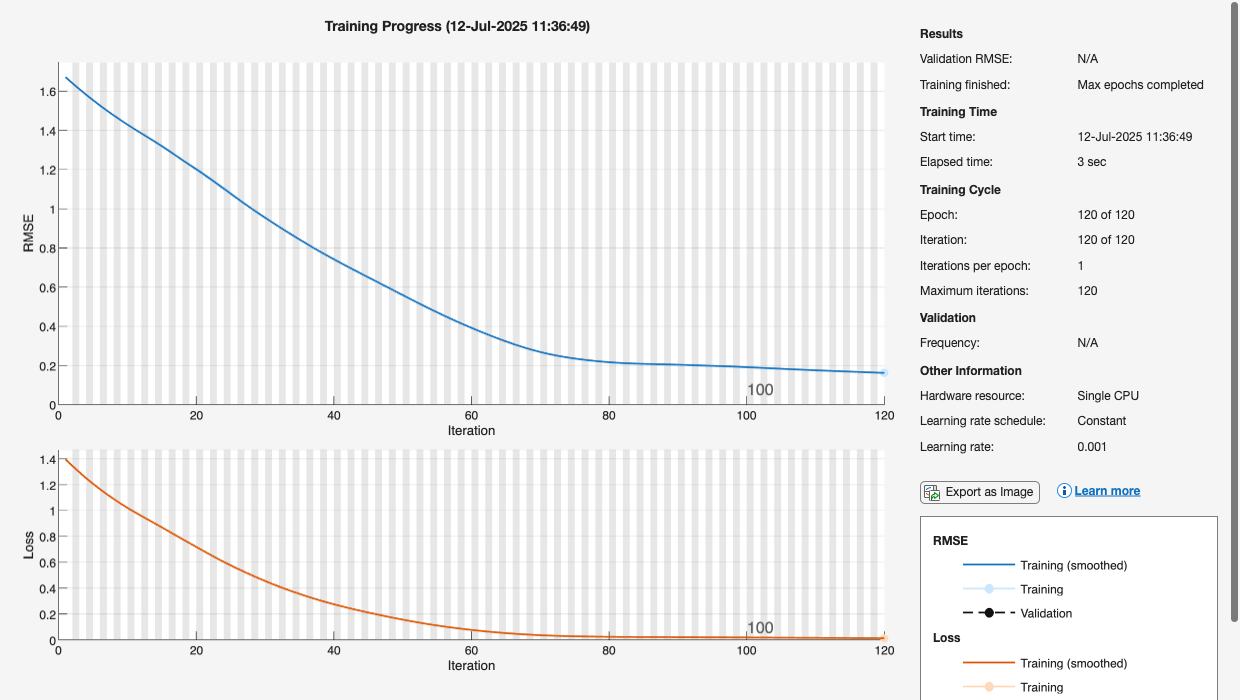

cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'MX201 Vibration Data for analysis.xlsx';
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);

features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];
features = rmmissing(features);  % remove NaNs

X = normalize(features{:,:}, 'range');

%% 20% training split
numTrain = round(0.5 * size(X, 1));
XTrain = {X(1:numTrain, :)'};  
Xseq   = {X'};                         

%% Define network
layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

%% Train
net = trainNetwork(XTrain, XTrain, layers, options);

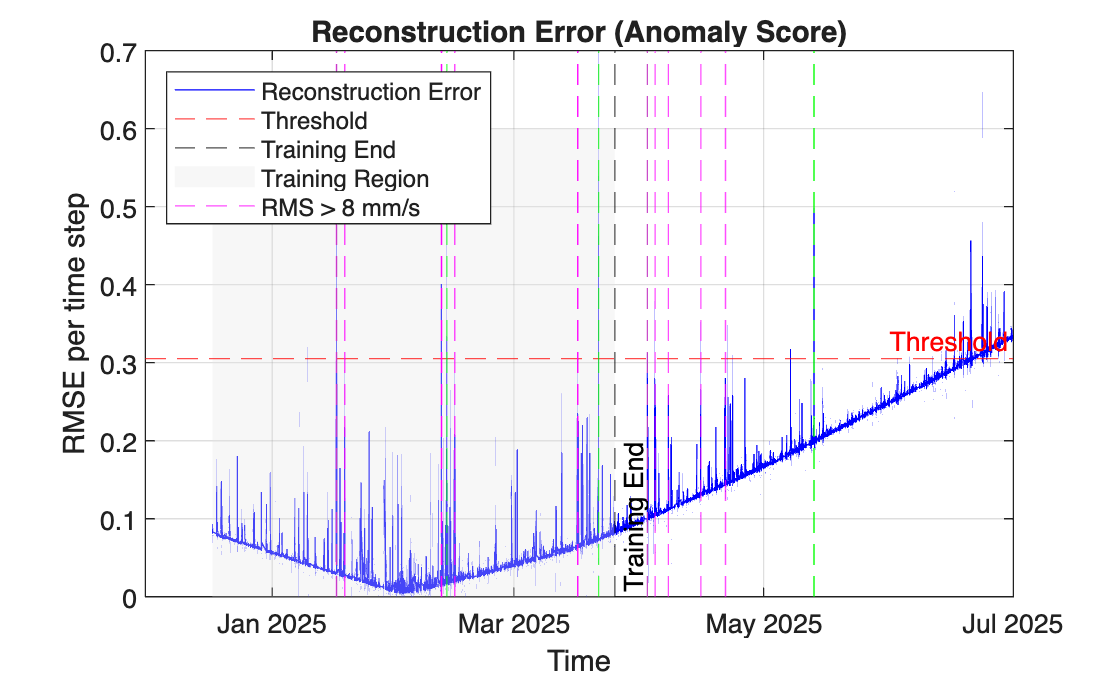


%% Predict
Ypred = predict(net, Xseq);
reconLoss = sqrt(mean((Xseq{1} - Ypred{1}).^2, 1));  
timestamps = data.DateTime(end - numel(reconLoss) + 1:end);

%% Plot
figure;
plot(timestamps, reconLoss, 'b');
hold on;

% Threshold
threshold = prctile(reconLoss, 95);
yline(threshold, '--r', 'Threshold');

% Mark end of training
trainEndTime = data.DateTime(numTrain);
xline(trainEndTime, '--k', 'Training End', 'LabelVerticalAlignment','bottom');

% Shade training region
yl = ylim;
fill([timestamps(1) trainEndTime trainEndTime timestamps(1)], ...
     [yl(1) yl(1) yl(2) yl(2)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.3);  % light gray

% Automatically mark all timestamps where any RMS > 8 mm/s
faultIdx = data.X_RMS > 8 | data.Y_RMS > 8 | data.Z_RMS > 8;
faultTimes = unique(data.DateTime(faultIdx));

% for i = 1:numel(faultTimes)
%     xline(faultTimes(i), '--m');
% end

% Reconstruct the mapping between timestamps and RMSE
rmseTimestamps = timestamps;
rmseValues = reconLoss;

for i = 1:numel(faultTimes)
    faultTime = faultTimes(i);

    % Find closest matching RMSE time index
    idx = find(rmseTimestamps == faultTime, 1);

    if ~isempty(idx)
        if rmseValues(idx) > threshold
            xline(faultTime, '--g');  % GREEN = fault + anomaly
        else
            xline(faultTime, '--m');  % MAGENTA = fault but not anomaly
        end
    else
        xline(faultTime, '--m');  % fallback if not in reconLoss timestamps
    end
end

% Final plot settings
title('Reconstruction Error (Anomaly Score)');
ylabel('RMSE per time step');
xlabel('Time');
legend('Reconstruction Error', 'Threshold', 'Training End', 'Training Region', 'RMS > 8 mm/s', 'Location', 'northwest');
grid on;

%% --------------------------------------------

    BatchNumber       BatchStartTime       Threshold                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 

% 🔁 Custom Batch-wise Anomaly Forecasting with ARIMA
% With defensive forecasting and forecast storage
% --------------------------------------------

% Definitions based on total size
totalSamples = size(X, 1);
batchLength = floor(0.5 * totalSamples);     % 34330 if total = 68660
stepSize = 100;
forecastHorizon = 600;

% Preallocate results table
numBatches = floor((totalSamples - batchLength - forecastHorizon) / stepSize);
results = table('Size', [numBatches 7], ...
    'VariableTypes', {'double','datetime','logical','double','cell','double','cell'}, ...
    'VariableNames', {'BatchNumber','BatchStartTime','DegradationDetected','StepsUntilThresholdCrossing','ForecastRMSE','Threshold','RMSE'});

% Save original training batch RMSE and threshold (first half of data)
XOriginalTrain = X(1:batchLength, :)';
YOriginalPred = predict(net, {XOriginalTrain});
reconTrain = sqrt(mean((XOriginalTrain - YOriginalPred{1}).^2, 1));
thresholdOriginal = prctile(reconTrain, 95);

% Store separately
originalTrainingRMSE = reconTrain;
originalTrainingThreshold = thresholdOriginal;

for b = 1:min(10, numBatches)   % ← change to "1:numBatches" for full run
    % Define window
    idxStart = 1 + (b-1) * stepSize;
    idxEnd = idxStart + batchLength - 1;
    predStart = idxEnd + 1;
    predEnd = predStart + forecastHorizon - 1;

    if predEnd > totalSamples
        break;
    end

    % Extract training batch
    XBatch = X(idxStart:idxEnd, :);
    XBatchCell = {XBatch'};

    % Train autoencoder on this batch
    layers = [
        sequenceInputLayer(size(X, 2))
        fullyConnectedLayer(32)
        reluLayer
        fullyConnectedLayer(16)
        reluLayer
        fullyConnectedLayer(32)
        reluLayer
        fullyConnectedLayer(size(X,2))
        regressionLayer
    ];

    options = trainingOptions('adam', ...
        'MaxEpochs', 120, ...
        'MiniBatchSize', 32, ...
        'InitialLearnRate', 1e-3, ...
        'Shuffle', 'every-epoch', ...
        'Plots', 'none', ...
        'Verbose', false);

    net = trainNetwork(XBatchCell, XBatchCell, layers, options);

    % Get reconstruction loss (RMSE)
    YpredBatch = predict(net, XBatchCell);
    reconBatch = sqrt(mean((XBatchCell{1} - YpredBatch{1}).^2, 1));
    thresholdBatch = prctile(reconBatch, 95);

    % Try ARIMA forecast safely
    try
        model = arima('ARLags',1,'D',1,'Constant',0);
        estModel = estimate(model, double(reconBatch'), 'Display', 'off');

        % Check model validity
        isModelValid = true;
        if isfield(estModel, 'AR') && all(isnan(estModel.AR))
            isModelValid = false;
        end
        if isfield(estModel, 'Variance') && (isempty(estModel.Variance) || isnan(estModel.Variance))
            isModelValid = false;
        end

        % Attempt forecast
        if isModelValid
            [forecastRMSE, ~] = forecast(estModel, forecastHorizon, 'Y0', double(reconBatch'));

            if isempty(forecastRMSE)
                warning("Batch %d: forecast() returned empty. Replacing with NaNs.", b);
                forecastRMSE = NaN(1, forecastHorizon);
            end
        else
            warning("Batch %d: ARIMA model invalid. Replacing with NaNs.", b);
            forecastRMSE = NaN(1, forecastHorizon);
        end

    catch ME
        warning("Batch %d: ARIMA forecast failed — %s", b, ME.message);
        forecastRMSE = NaN(1, forecastHorizon);
    end

    % Store forecast vector regardless
    results.BatchNumber(b) = b;
    results.BatchStartTime(b) = timestamps(idxStart);
    results.ForecastRMSE{b} = forecastRMSE;
    results.Threshold(b) = thresholdBatch;
    results.RMSE{b} = reconBatch;

    % Check for threshold crossing
    idxCross = find(forecastRMSE > thresholdBatch, 1);
    if ~isempty(idxCross)
        results.DegradationDetected(b) = true;
        results.StepsUntilThresholdCrossing(b) = idxCross;
    else
        results.DegradationDetected(b) = false;
        results.StepsUntilThresholdCrossing(b) = NaN;
    end
end

% Show the results table
disp(results);

figure;
plot(1:height(data), data.X_RMS, 'r');
hold on;
plot(1:height(data), data.Y_RMS, 'g');
plot(1:height(data), data.Z_RMS, 'b');
xlabel('Sample Index');
ylabel('RMS Value');
legend('X', 'Y', 'Z');
title('Raw RMS vs. Sample Index');
grid on;

figure;
plot(reconBatch, 'b.-');
title(sprintf("RMSE in Batch %d", b));
xlabel("Time step within batch");
ylabel("Anomaly Score (RMSE)");
grid on;

batchNum = 10;

forecast = results.ForecastRMSE{batchNum};

figure;
plot(forecast, 'b.-');
yline(prctile(forecast, 95), '--r', '95% Forecast Percentile');
title(sprintf('Forecasted RMSE - Batch %d', batchNum));
xlabel('Forecast Step');
ylabel('Forecasted RMSE');
grid on;